# PHY 329 Homework 3

## Ryan Schlimme (eid: rjs4499)

# Problem 7.7

Find the maximum of the functon

f = @(x) 4*x - 1.8*x.^2 + 1.2*x.^3 - 0.3*x.^4

f = function_handle with value:
    @(x)4*x-1.8*x.^2+1.2*x.^3-0.3*x.^4


## Part a) Golden-Section Search

Using xl = -2, xu = 4, error = 1%

xl = -2;
xu = 4;
es = 1;

[x,fx] = goldmin(@(x) f(x)*-1, xl, xu, es)

x = 2.3282

fx = -5.8853

Using Golden-Section search, we find maximum of 5.8853 at x = 2.3282.

## Part b) Parabolic Interpolation

x1 = 1.75, x2 = 2, x3 = 2.5, iterations = 5

x1 = 1.75

x1 = 1.7500

x2 = 2

x2 = 2

x3 = 2.5

x3 = 2.5000

iters = 5

iters = 5



[x, fx] = parabolicmin(@(x) f(x)*-1, x1, x2, x3, iters)

x = 2.3112

fx = -5.8846

Using parabolic interpolation we find a maximum of 5.8846 at x = 2.3112.

# Problem 7.11

The following function has several unequal minima over the interval x: [2,20]

f = @(x) sin(x) + sin(2*x/3)

f = function_handle with value:
    @(x)sin(x)+sin(2*x/3)


## Part a) Plot

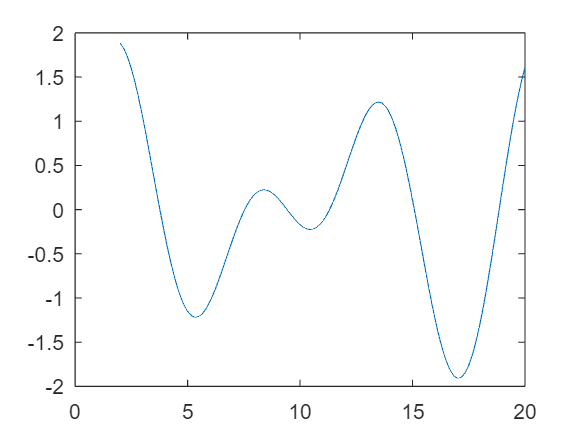

xRange = 2: 0.01 : 20;

grid on;
figure(1); plot(xRange, f(xRange))

## Part b) fminbnd

Use initial guesses of [4,8]

[x, fx] = fminbnd(f, 4, 8)

x = 5.3622

fx = -1.2160

Using these guesses, we find minimum value of -1.2160 at x = 5.3622.

## Part c) Golden-Section by Hand

Use same initial guesses and stopping criterion of 3 significant figures

# Problem 7.25

f = @(x) 2*x(2).^2 - 2.25*x(1)*x(2) - 1.75*x(2) + 1.5*x(1).^2

f = function_handle with value:
    @(x)2*x(2).^2-2.25*x(1)*x(2)-1.75*x(2)+1.5*x(1).^2



a = [0,0]

a =      0     0



fminsearch(f, a)

ans =     0.5676    0.7568



f([.5676, .7568])

ans = -0.6622

Using fminsearch, we find a minima at x = 0.5676, y = 0.7568

# Problem 7.26

f = @(x) 4*x(1) + 2*x(2) + x(1).^2 -2*x(1).^4 + 2*x(1)*x(2) - 3*x(2).^2

f = function_handle with value:
    @(x)4*x(1)+2*x(2)+x(1).^2-2*x(1).^4+2*x(1)*x(2)-3*x(2).^2



a = [0,0]

a =      0     0



fminsearch(@(x) f(x)*-1, a)

ans =     0.9676    0.6559



f([0.9676, 0.6559])

ans = 4.3440

Using fminsearch with a vertically reflected function, we find a maximum at x = 0.9676, y = 0.6559

# Problem 7.37

Develop the potential energy function for the system. Make contour and surface plots in MATLAB. Minimize potential energy function to determine equilibrium displacements x1 and x2 given forcing function F = 100 N and ka = 20 and kb = 15 N/m

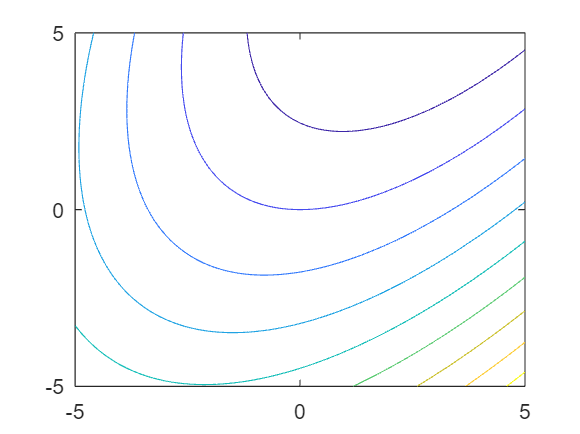

ka = 20;
kb = 15;
F = 100;

PE = @(x,y) 0.5*20*x.^2 + 0.5*15*(y-x).^2 - 100*y;

fcontour(PE)

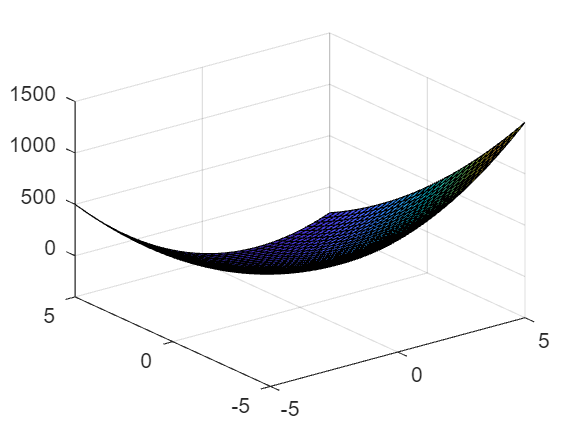

fsurf(PE)


PE = @(x) 0.5*20*x(1).^2 + 0.5*15*(x(2)-x(1)).^2 - 100*(x(2));
x = [0,0];

fminsearch(PE, x)

ans =     5.0001   11.6667



PE([5.0001, 11.6667])

ans = -583.3333

Using fminsearch, I found that the values of x1 and x2 that minimize the potential energy are 5.0001 and 11.6667 m.

# Problem 14.7

The data was collected to determine the relationship between pressure (P) and temperature (T) of a fixed volume (10 m^3) of 1 kg of Nitrogen (N2). Using the ideal gas law, determine R. T must be in Kelvin, but is given in degrees C.

T = [-40, 0, 40, 80, 120, 160]

T =    -40     0    40    80   120   160


P = [6900, 8100, 9350, 10500, 11700, 12800]

P =         6900        8100        9350       10500       11700       12800



Tk = 273 + T

Tk =    233   273   313   353   393   433



n = 1/0.02802

n = 35.6888


polyfit(Tk, P, 1)

ans =    29.6071   32.4881



29.6071*10/n

ans = 8.2959

Our fit gives us a non-zero intercept which is theoretically incorrect. However, it gives us a slope, which when multiplied by V and divided by n, yields a gas constant R = 8.2959 J/(mol K) which is close to the accepted value of 8.3145 J/(mol K).

# Problem 14.12

The surface area of humans is related to weight (W) and height (H). All individuals of 180 cm height and different weights have surface areas measured as follows. Use a power law to fit the data well. Evaluate a and b. Predict surface area of 95 kg person (assuming 180 cm height).

% A = a*W^b

W = [70, 75, 77, 80, 82, 84, 87, 90]

W =     70    75    77    80    82    84    87    90


A = [2.10, 2.12, 2.15, 2.20, 2.22, 2.23, 2.26, 2.30]

A =     2.1000    2.1200    2.1500    2.2000    2.2200    2.2300    2.2600    2.3000



lnW = log(W)

lnW =     4.2485    4.3175    4.3438    4.3820    4.4067    4.4308    4.4659    4.4998


lnA = log(A)

lnA =     0.7419    0.7514    0.7655    0.7885    0.7975    0.8020    0.8154    0.8329



polyfit(lnW, lnA, 1)

ans =     0.3799   -0.8797



exp(-0.8797)

ans = 0.4149


0.4149*95^0.3799

ans = 2.3403

We are given a slope of 0.3799 and an intercept of -0.8797. When we transform our equation back to exponential, we yield a model of A = 0.4149*W^0.3799. Therefore, a = 0.4149 and b = 0.3799. Using this model, we predict the surface area of a 95 kg individual to be 2.3403 m^2.

# Problem 15.3

Fit a cubic polynomial to the data. Along with coefficients, determine r^2 and s (y/x) aka the standard error.

x = [3, 4, 5, 7, 8, 9, 11, 12]

x =      3     4     5     7     8     9    11    12


y = [1.6, 3.6, 4.4, 3.4, 2.2, 2.8, 3.8, 4.6]

y =     1.6000    3.6000    4.4000    3.4000    2.2000    2.8000    3.8000    4.6000



p = polyfit(x, y, 3)

p =     0.0467   -1.0412    7.1438  -11.4887


yfit = polyval(p, x);          
SStot = sum((y-mean(y)).^2);                   
SSres = sum((y-yfit).^2);                      
Rsq = 1-SSres/SStot

Rsq = 0.8290


sqrt(SSres / (length(x) - (length(p))))

ans = 0.5700

Our cubic polynomial is 0.0467x^3 -1.0412x^2 + 7.1438x - 11.4887 with an r squared of 0.829. The standard error is 0.5700.

# Problem 15.28

Perform a nonlinear regression for the data according to the model

model = @(b,t) b(1)*exp(-1.5*t) + b(2)*exp(-0.3*t) + b(3)*exp(-0.05*t)

model = function_handle with value:
    @(b,t)b(1)*exp(-1.5*t)+b(2)*exp(-0.3*t)+b(3)*exp(-0.05*t)



t = [0.5, 1, 2, 3, 4, 5, 6, 7, 9]

t =     0.5000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    9.0000


p = [6, 4.4, 3.2, 2.7, 2.2, 1.9, 1.7, 1.4, 1.1]

p =     6.0000    4.4000    3.2000    2.7000    2.2000    1.9000    1.7000    1.4000    1.1000



beta0 = [0,0,0]

beta0 =      0     0     0



nlinfit(t, p, model, beta0)

ans =     4.0046    2.9213    1.5647


We receive values for our model of A = 4.0046, B = 2.9213, C = 1.5647 using MATLAB to perform a nonlinear fit.

# Problem 16.2

Temperature varies sinusoidally over the year. Use linear LSR to fit the data. Determine the mean, amplitude, and date of maximum temperature. The period is 365 days.

t = [15, 45, 75, 105, 135, 165, 225, 255, 285, 315, 345]
T = [3.4, 4.7, 8.5, 11.7, 16, 18.7, 19.7, 17.1, 12.7, 7.7, 5.1]

B = 2*pi / 365

model = @(b,t) b(1)*sin(B*(t - b(2))) + b(3)

beta0 = [1,1,1]

b = nlinfit(t, T, model, beta0)

365/4+8.1073

xRange = 0: 0.01 : 400;

grid on;
figure(1); plot(xRange, model(b, xRange))

fminbnd(@(t) model(b, t)*-1, 100, 300)

470.9652 +91.25

Using a nonlinear fit, we find A = 8.4418, B = 470.9652, C = 12.0341. This corresponds to a function T = 8.4418 * sin(0.0172*t - 470.9652)+12.0341. Therefore, the mean temperature is 12.0341 degress C. The amplitude is 8.4418 degrees C. The right shift of 470.9652 shifts the maximum from day 365/4 = 91.25 to day 197.2152, approximately June 28.

# Define Our Functions

% Golden Section Minimum

function [x, fx, ea, iter] = goldmin(f, xl, xu, es, maxit, varargin)
% inputs: 
%   f = function
%   xl, xu = lower and upper guesses
%   es = desired relative error (as a percent)
%   maxit = maximum iterations
% outputs:
%   x = minimum location
%   fx = minimum value
%   ea = error (as a percent)
%   iter = number of iterations
if nargin<3, error("at least 3 input args required"), end
if nargin<4||isempty(es), es = 0.0001; end
if nargin<5||isempty(maxit), maxit = 50; end
phi=(1+sqrt(5))/2; iter = 0;
d = (phi-1)*(xu-xl);
x1 = xl + d; x2 = xu -d;
f1 = f(x1, varargin{:}); f2 = f(x2, varargin{:});
while(1)
    xint = xu - xl;
    if f1 < f2
        xopt = x1; xl = x2; x2 = x1; f2=f1;
        x1 = xl + (phi-1)*(xu-xl); f1 = f(x1, varargin{:});
    else
        xopt = x2; xu = x1; x1 = x2; f1=f2;
        x2 = xu - (phi-1)*(xu-xl); f2 = f(x2, varargin{:});
    end
    iter = iter + 1;
    if xopt ~= 0, ea = (2 - phi)*abs(xint/xopt)*100; end
    if ea <= es || iter >= maxit, break, end
end
x = xopt; fx = f(xopt, varargin{:});
end

% Parabolic Interpolation Minimum
function [x, fx] = parabolicmin(f, x1, x2, x3, iters)
% inputs: 
%   f = function
%   x1, x2, x3 = three x values
%   iters = number of iterations
% outputs:
%   x = minimum location
%   fx = minimum value
if nargin<5, error("missing inputs"), end
iter = 1; 
while(1)
    x4 = x2 - 0.5*((x2 - x1).^2 * (f(x2)-f(x3))-(x2 - x3).^2 * (f(x2)-f(x1))) / ((x2 - x1)* (f(x2)-f(x3))-(x2 - x3) * (f(x2)-f(x1)));
    if f(x4) < f(x2)
        if x4 > x2
            x1 = x2;
            x2 = x4;
        else
            x3 = x2;
            x2 = x4;
        end
    end
    iter = iter + 1;
    if iter > iters, break, end
end
x = x4; fx = f(x4);
end

% Linear Regression